### `In the name of God`

# Digital Communications LAB

# Lab#1

**Ashkan Jafari 810197483**

## Question1.

### 1.1

format long
A = [2709/1024 10583/4000 2024/765]'

A =    2.645507812500000
   2.645750000000000
   2.645751633986928


sqrt(7)

ans =    2.645751311064591


So 2024/765 would be a better approximation.

A = abs(A - sqrt(7));
[value, index]=min(A)

value =      3.229223373146795e-07


index =      3


So 2024/765 would be a better approximation.

a = sym(3^301);
vpa(a,15)

$$ans = 4.10674437175765e+143$$

format long
b = sym(3^301)

$$b = 410674437175765160820361694174843802787546092152263204276061421137680115001109947317381348595546423243177970334421273291830236683739419899854848$$

20/3 - 20*(1/3)

ans =      8.881784197001252e-16


20/3

ans =    6.666666666666667


20*(1/3)

ans =    6.666666666666666


The reason of this difference is because of 1/3.

In 20/3, 20 is going to divided by 3 and then will be shown. But in 20*(1/3), first (1/3) is calculated and rounded by the floating digits which matlab has and then this rounded number will be multiplied by 20.

format

a = 10^16 + 1 - 10^16

a = 0

As we know Matlab saves only 15 digits in default mode so because 1 is much lower than 10^16, Matlab do not consider it!

b = 10^16 - 10^16

b = 0

b + 1

ans = 1

### 1.2

format long
cosh(0.1)

ans =    1.005004168055804


log(2)

ans =    0.693147180559945


atan(1/2)

ans =    0.463647609000806


### 1.3

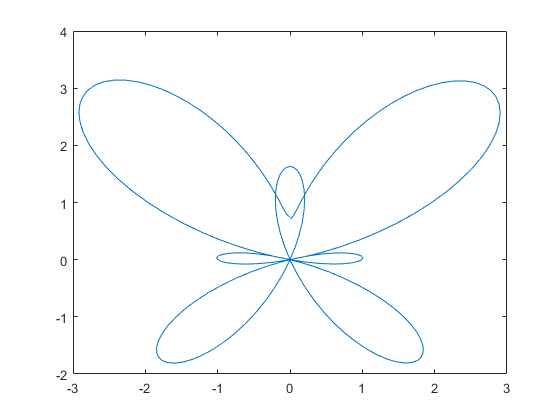

t1 = 0:pi/100:2*pi;
t2 = 0:pi/100:10*pi;

x = sin(t1).*(exp(cos(t1))-2*cos(4*t1)+(sin(t1/12)).^5);
y = cos(t1).*(exp(cos(t1))-2*cos(4*t1)+(sin(t1/12)).^5);
plot (x,y)

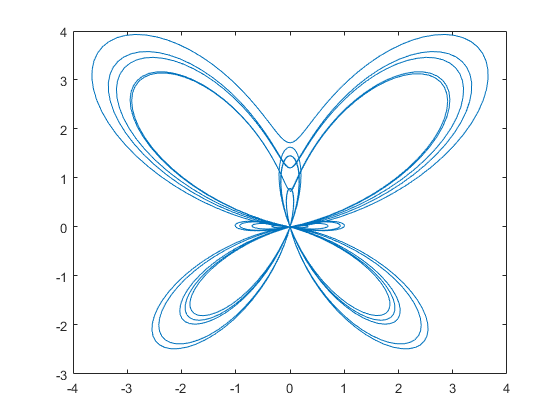

x = sin(t2).*(exp(cos(t2))-2*cos(4*t2)+(sin(t2/12)).^5);
y = cos(t2).*(exp(cos(t2))-2*cos(4*t2)+(sin(t2/12)).^5);
plot(x,y)

## Question2.

### 2.1

(2*(3<8/4 + 2)^2) < (-2)^3

ans = logical
   0


The left side is 2*(1)^2 = 2, The right side is -8. 2 is not lower than -8 so the value of comparison is 0!

(5 + ~0)/3 == 3 - ~(10/5 - 2)

ans = logical
   1


The left side : (5+1)/3=2

The right side : 3 - (1) = 2    ===> 2 == 2 is true! 

~4 < 5 | 0 >= 12/6

ans = logical
   1


Based on the order and priority in math and matlab the equality would be as: (~4<5) | (0>=2) which will be (1 | something) = 1

-7 < -5 < -2 & 2 + 3 <= 15/3

ans = logical
   0


Based on the order and priority in math and matlab the equality would be as : ((-7 < -5) < -2) & 2 + (3 <=5) which will be (0 & something) = 0

### 2.2

With Matlab Functions:

abs(pascal(7,1))

ans =      1     0     0     0     0     0     0
     1     1     0     0     0     0     0
     1     2     1     0     0     0     0
     1     3     3     1     0     0     0
     1     4     6     4     1     0     0
     1     5    10    10     5     1     0
     1     6    15    20    15     6     1


From Scratch:

Note that in this part:

1) I define the first elements

2) Iterate over the other rows from r=3 to 7 and inside that from 2 to r and then evaluate the new values based on previous ones.  

n = 7;

m(1, 1) = 1;
m(2, 1 : 2) = [1 1]; 

for r = 3 : n
    m(r, 1) = 1;   
    for c = 2 : r-1
        m(r, c) = m(r-1, c-1) + m(r-1, c);
    end   
    m(r, r) = 1;
end
m

m =      1     0     0     0     0     0     0
     1     1     0     0     0     0     0
     1     2     1     0     0     0     0
     1     3     3     1     0     0     0
     1     4     6     4     1     0     0
     1     5    10    10     5     1     0
     1     6    15    20    15     6     1


### 2.3

n=3;
i=1:n;
j=1:n;
A=1./(i+j'-1)

A =    1.000000000000000   0.500000000000000   0.333333333333333
   0.500000000000000   0.333333333333333   0.250000000000000
   0.333333333333333   0.250000000000000   0.200000000000000


n=500;
i=1:n;
j=1:n;
A=1./(i+j'-1);
max(eig(A))

ans =    2.376896505684826


### 2.4

The only thing which should be mentioned is that our condition for while loop is that if there is no even element then end the procedure.

rng(1)
v = randi([10,30],20,1);
i = 1;
while sum(mod(v,2)==1) 
    v(mod(v,2)==1) = randi([10,30],sum(mod(v,2)==1),1);
    i = i+1;
end
sprintf('The vector Generated After %d iteration(s).',i)

ans = 'The vector Generated After 3 iteration(s).'